# Løsning til 2015F

## Opgave 1

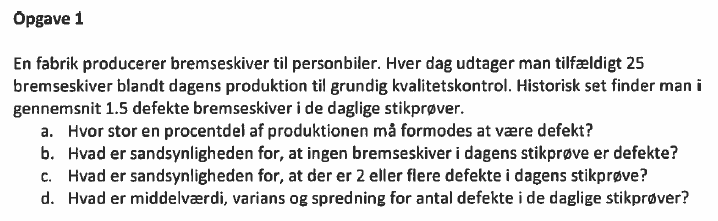

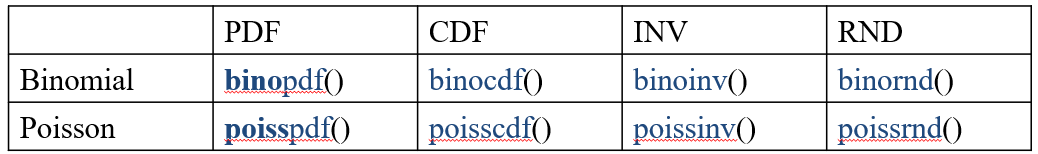

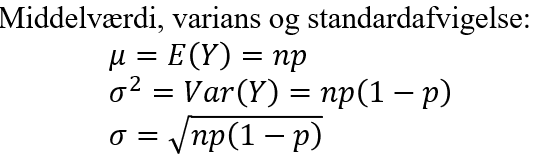

clc; clear all;

% Stikprøve på N = 25
N = 25;         % Udtagede bremseskiver
n_defekt = 1.5; % Antal defekte pr dag

% Opgave a
n_defekt_procent = n_defekt/N

n_defekt_procent = 0.0600


% Opgave b - binomialfordelt variabel
antal_defekte = 0;  % Ingen "succeser", hvor succes er defekt
ingen_defekte = binopdf(antal_defekte, N, n_defekt_procent)

ingen_defekte = 0.2129


% Opgave c - P(Y >= 2)
% P(Y >= 2) = 1 - P(Y = 0) - P(Y = 1)
ssh = 1 - ingen_defekte - binopdf(1, N, n_defekt_procent)

ssh = 0.4473


n_defekte_c = 2

n_defekte_c = 2

ssh2 = binocdf(N - n_defekte_c, N, 1 - n_defekt_procent)

ssh2 = 0.4473


% Opgave d - deskriptorer
mu = N * n_defekt_procent

mu = 1.5000

varians = N*n_defekt_procent*(1 - n_defekt_procent)

varians = 1.4100

std = sqrt(varians)

std = 1.1874